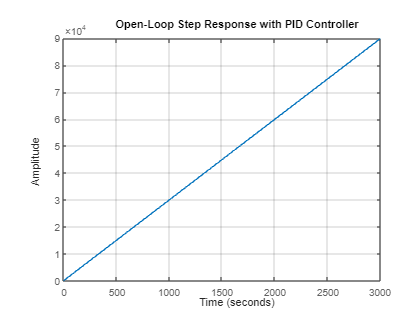

% Define the constants
k0 = 1.3;
b = 12;
a1 = 3;
a2 = 5;
a3 = 2;

% Define the numerator and denominator of the transfer function
num = k0 * [1 b];
den = conv(conv([1 a1], [1 a2]), [1 a3]);

% Create the transfer function for the plant G(s)
G = tf(num, den);

% Ziegler-Nichols Tuning

Kp = (1.5/0.125)*1.2;
Ti = 2*0.125;
Td = 0.5*0.125;

% Create the PID controller
PID = pid(Kp, Kp/Ti, Kp*Td);

% Open-Loop Transfer Function (Plant * PID)
OLTF = PID * G;

% Closed-Loop Transfer Function (with feedback)
CLTF = feedback(OLTF, 1);


% Plot the step response of the OLTF
figure;
step(OLTF);
title('Open-Loop Step Response with PID Controller');
grid on;

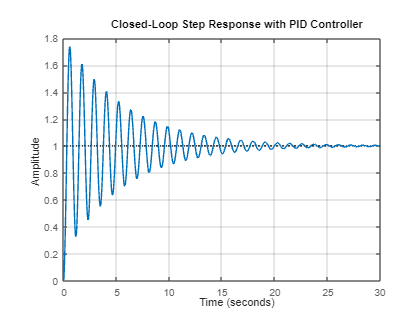


% Plot the step response of the CLTF
figure;
step(CLTF);
title('Closed-Loop Step Response with PID Controller');
grid on;